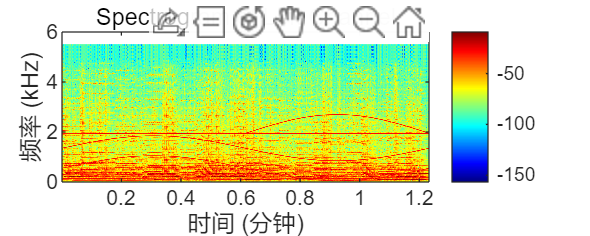

clear all; close all; clc;

% 加载数据
% data = load('Hw2e.mat');
% Sin_e = data.Sin_e;   % 大多数数据用这个命名

data = load('Hw2d.mat');
Sin_x = data.Sin_d;   % 大多数数据用这个命名

fs = data.fs;

signal_L = Sin_x(:,1);   % 左声道
signal_R = Sin_x(:,2);   % 右声道

% 设置时频分析参数
win_len = 1024;
overlap = round(0.75 * win_len);
nfft = 2048;

% 左声道频谱图
figure('Name', 'Left Channel Spectrogram', 'Position', [100, 100, 1000, 400]);
spectrogram(signal_L, win_len, overlap, nfft, fs, 'yaxis');
title('Spectrogram of Left Channel');
ylim([0 6]); % 单位为 kHz；可根据需要调整
colormap jet; colorbar;

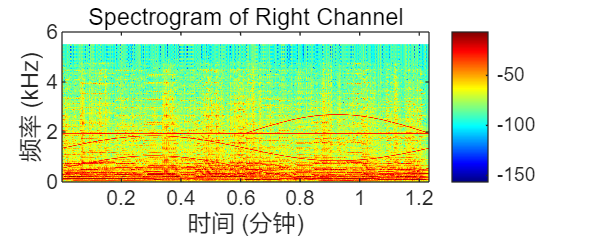


% 右声道频谱图
figure('Name', 'Right Channel Spectrogram', 'Position', [100, 100, 1000, 400]);
spectrogram(signal_R, win_len, overlap, nfft, fs, 'yaxis');
title('Spectrogram of Right Channel');
ylim([0 6]); % 单位为 kHz；可根据需要调整
colormap jet; colorbar;